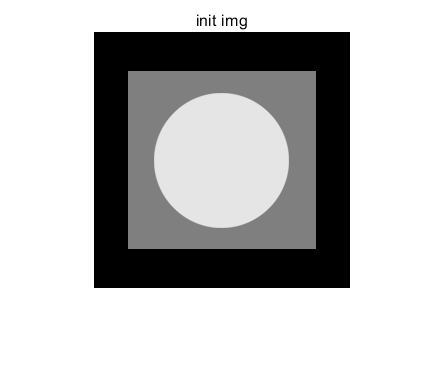

load Q2\init_img.mat
%imshow(init_img);
%help imnoise
a=init_img;
imshow(a);title("init img");

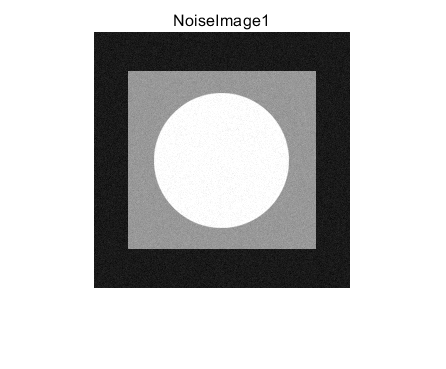

b=imnoise(a,'gaussian',25/255,25/255/255);
c=imnoise(a,'salt & pepper',0.05);
imshow(b);title("NoiseImage1");

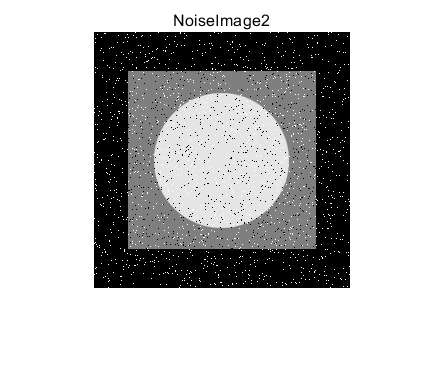

imshow(c);title("NoiseImage2");

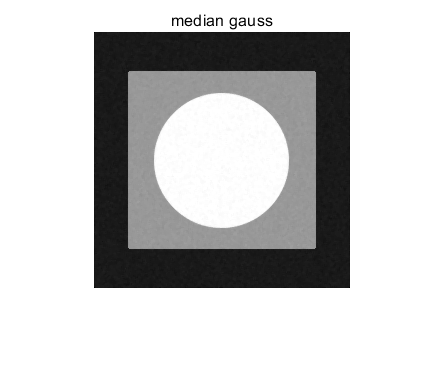


median_gauss=medfilt2(b);
median_saltpaper=medfilt2(c);

x=fspecial('average');
mean_gauss=imfilter(b,x);
mean_saltpaper=imfilter(c,x);

imshow(median_gauss);title("median gauss");

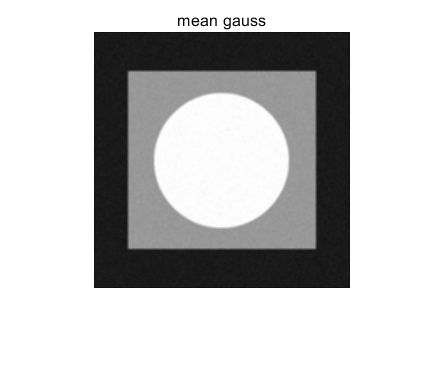

imshow(mean_gauss);title("mean gauss");

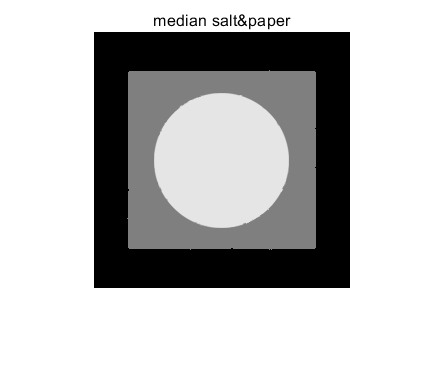

imshow(median_saltpaper);title("median salt&paper");

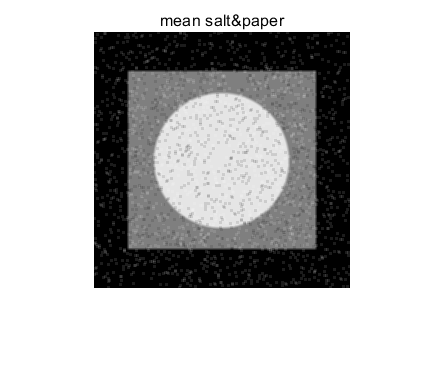

imshow(mean_saltpaper);title("mean salt&paper");

%help medfilt2
%help filter2
%help medfilt2
%help meanfilt2